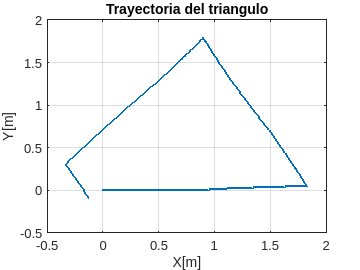

clear all;
clc;
close all;

bagReader = ros2bagreader("lab6_triangulo/");
baginfo = ros2("bag","info","lab6_triangulo/");

msgs = readMessages(bagReader);

bagSelL = select(bagReader,"Topic", "/positionX");
bagSelR = select(bagReader,"Topic", "/positionY");

msgsFilteredL = readMessages(bagSelL);
msgsFilteredR = readMessages(bagSelR);

msgsFilteredL{1};
msgsFilteredR{1};

xPoints = cellfun(@(m) double(m.data),msgsFilteredL);
yPoints = cellfun(@(m) double(m.data),msgsFilteredR);
plot(xPoints, yPoints, 'LineWidth', 2)
grid on
xlabel('X[m]')
ylabel('Y[m]')
title('Trayectoria del triangulo')